% Define the parameters for the Gaussian mixture
K = 4;
mu = N_0; % means for each mixture component
sigma = N_1; % initialize covariance matrices

% Compute the Gaussian mixture PDF on a grid of points
x = linspace(min(data(:,1)), max(data(:,1)), 100);
y = linspace(min(data(:,2)), max(data(:,2)), 100);
[X,Y] = meshgrid(x,y);
xy = [X(:) Y(:)];
pdf = zeros(length(xy),K);
for k = 1:K
    pdf(:,k) = pi(k)*mvnpdf(xy, mu(k,:), sigma(:,:,k));
end
pdf = sum(pdf,2);
pdf = reshape(pdf, size(X));

% Draw the 2D histogram and the Gaussian mixture on one plot
figure;
gcf=figure

gcf =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 98 560 420]
       Units: 'pixels'

  Show all properties


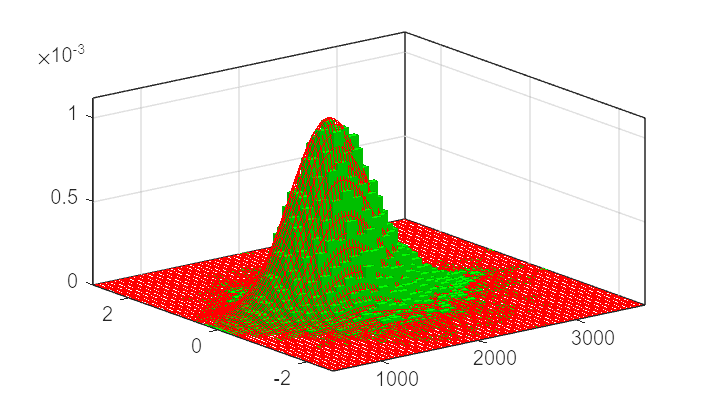

set(gcf, 'Units', 'inches', 'Position', [0, 0, 12, 7]);
%set(gcf, 'Renderer', 'painters'); % set renderer to painters for vector graphics
set(0, 'DefaultTextFontName', 'Serif', 'DefaultTextFontSize', 14); % set font properties
histogram2(data(:,1), data(:,2), 'Normalization', 'pdf', 'EdgeAlpha', 0, 'FaceColor', 'green');
hold on;
surf(X, Y, pdf, 'LineWidth', 0.5, 'EdgeColor', 'red', 'EdgeAlpha', 1, 'FaceAlpha', 0);

% export plot to PDF
exportgraphics(gcf, 'histogram&gaussian.png', 'Resolution', 240, 'BackgroundColor', 'none');